# Actividad 5

## Robot mixto

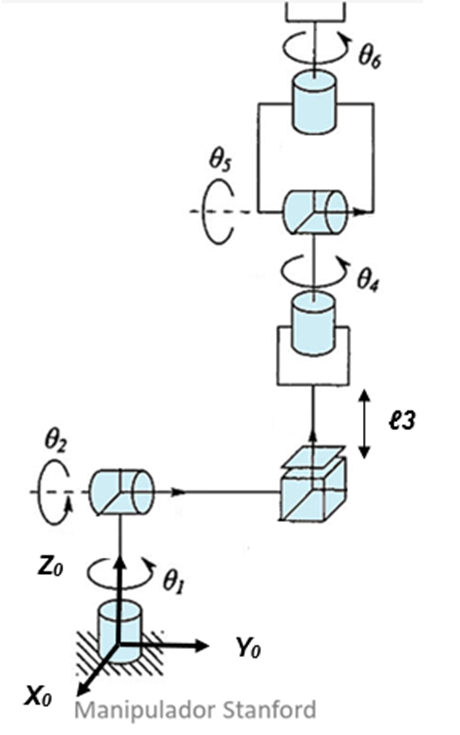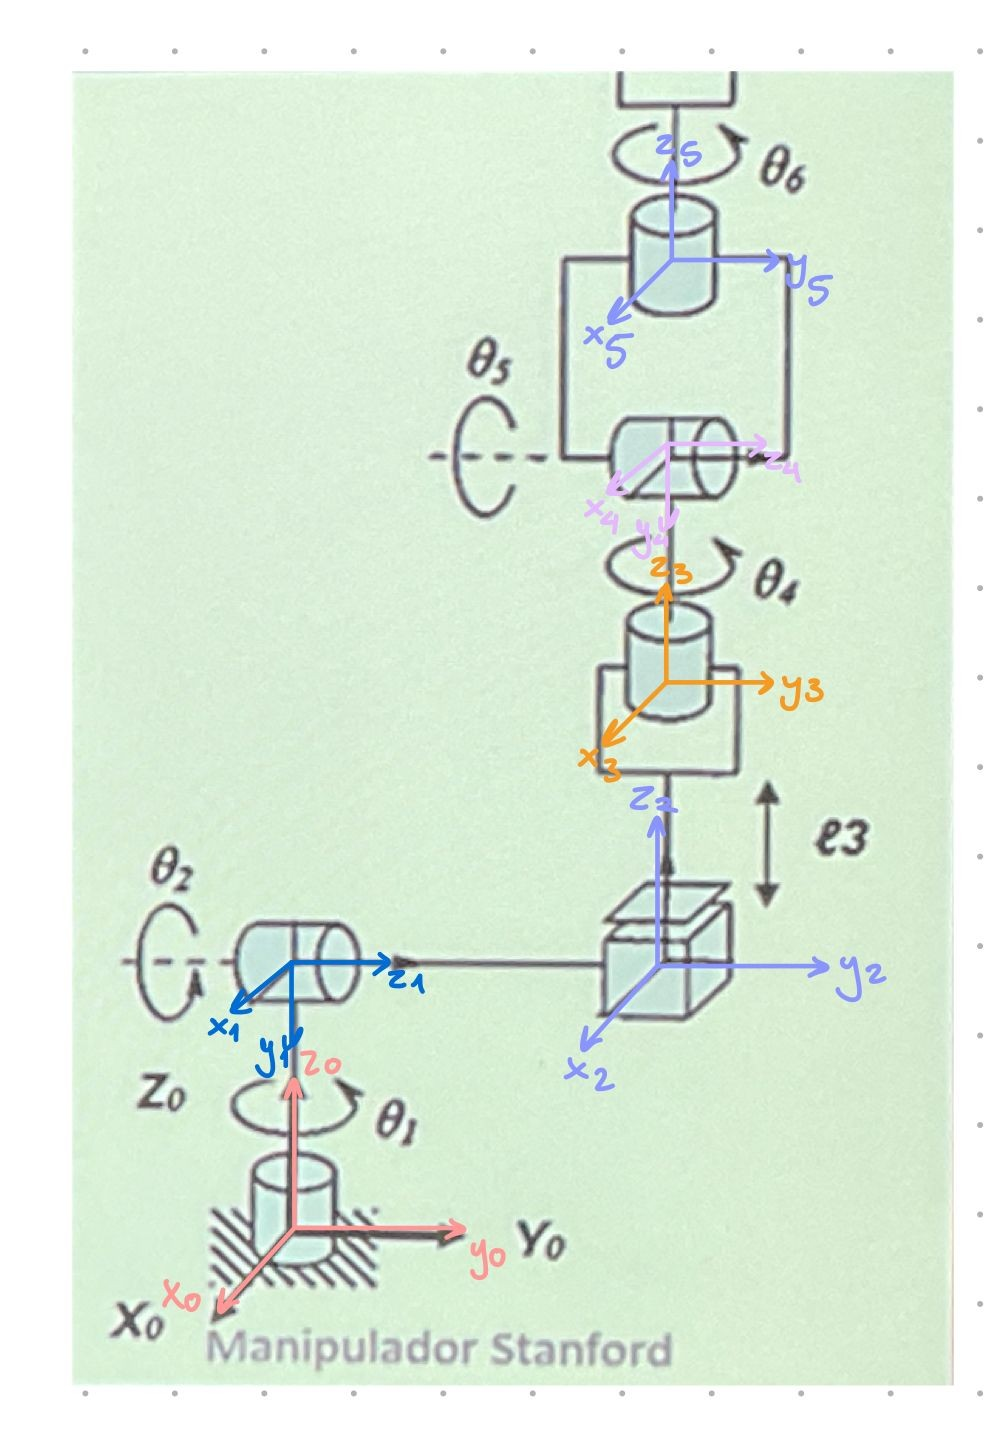

%Limpieza de pantalla
clear all
close all
clc

tic
%Declaración de variables simbólicas
syms th1(t) th2(t) l3(t) th4(t) th5(t) th6(t) t
syms th1p(t) th2p(t) l3p(t) th4p(t) th5p(t) th6p(t)
syms th1pp(t) th2pp(t) l3pp(t) th4pp(t) th5pp(t) th6pp(t)
syms m1 m2 m3 m4 m5 m6 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3 Ixx4 Iyy4 Izz4 Ixx5 Iyy5 Izz5 Ixx6 Iyy6 Izz6
syms l1 l2 l4 l5 lc1 lc2 lc3 lc4 lc5 lc6
syms pi g a cero

 Q= [th1; th2; l3; th4; th5; th6];
 Qp= [th1p; th2p; l3p; th4p; th5p; th6p];
 Qpp= [th1pp; th2pp; l3pp; th4pp; th5pp; th6pp];

RP=[0 0 1 0 0 0];

GDL= size(RP,2);
GDL_str= num2str(GDL);

%Junta 1
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0; 0;l1];
R(:,:,1)= [cos(th1)  0   -sin(th1);
           sin(th1)  0    cos(th1);
           0         -1         0];

%Junta 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0 ; 0 ; l2];
R(:,:,2)= [cos(th2)     0        sin(th2);
           sin(th2)     0        -cos(th2);
           0            1        0];

%Junta 3
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0;0;l3];
R(:,:,3)= [1  0  0;
           0  1  0;
           0  0  1];

%Junta 4
%Posición de la articulación 4 respecto a 3
P(:,:,4)= [0;0;l4];
R(:,:,4)= [cos(th4) 0     -sin(th4);
           sin(th4) 0     cos(th4);
           0        -1        0];

%Junta 5
%Posición de la articulación 5 respecto a 4
P(:,:,5)= [l5*cos(th5); -l5*sin(th5); 0];
R(:,:,5)= [cos(th5)     0    sin(th5);
           sin(th5)     0    -cos(th5);
           0            1        0];

%Junta 6
%Posición de la articulación 6 respecto a 5
P(:,:,6)= [0; 0 ;0];
R(:,:,6)= [cos(th6)   -sin(th6)  0;
           sin(th6)    cos(th6)  0;
               0         0       1];

Vector_Zeros= zeros(1, 3);

A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
PO(:,:,GDL)= P(:,:,GDL);
RO(:,:,GDL)= R(:,:,GDL);


for i = 1:GDL
    i_str= num2str(i);
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);

    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
end

%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 6  %%%%%%%%%%

Jv_a6(:,GDL)=PO(:,:,GDL);
Jw_a6(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0
        try
            Jv_a6(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a6(:,k)= RO(:,3,k-1);
        catch
            Jv_a6(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a6(:,k)=[0,0,1];
        end
    else
        try
            Jv_a6(:,k)= RO(:,3,k-1);
        catch
            Jv_a6(:,k)=[0,0,1];
        end
            Jw_a6(:,k)=[0,0,0];
    end
end

Jv_a6= simplify(Jv_a6);
Jw_a6= simplify(Jw_a6);
Jac6= [Jv_a6; Jw_a6];
Jacobiano6= simplify(Jac6);

disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 6');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 6


V6=simplify(Jv_a6*Qp);
pretty(V6)

/ cos(th1(t)) th2p(t) #1 - th1p(t) (l2 cos(th1(t)) + l4 sin(th1(t)) sin(th2(t)) + l5 cos(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) + sin(th1(t)) sin(th2(t)) l3(t) + l5 sin(th1(t)) sin(th2(t)) sin(th5(t))) - th5p(t) (l5 cos(th1(t)) cos(th5(t)) sin(th2(t)) + l5 sin(th1(t)) sin(th4(t)) sin(th5(t)) - l5 cos(th1(t)) cos(th2(t)) cos(th4(t)) sin(th5(t))) + cos(th1(t)) sin(th2(t)) l3p(t) - l5 cos(th5(t)) th4p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               


disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 6');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 6


W6=simplify(Jw_a6*Qp);
pretty(W6)

/ cos(th1(t)) sin(th2(t)) th4p(t) - th6p(t) (sin(th5(t)) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t))) - cos(th1(t)) cos(th5(t)) sin(th2(t))) - sin(th1(t)) th2p(t) - th5p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) \
|                                                                                                                                                                                                                                                               |
| th5p(t) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) + th6p(t) (sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) + cos(th5(t)) sin(th1(t)) sin(th2(t))) + cos(th1(t)) th2p(t) + sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                                                                                                                                                                                                 


%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 5  %%%%%%%%%%

Jv_a5(:,GDL-1)=PO(:,:,GDL-1);
Jw_a5(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0
        try
            Jv_a5(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a5(:,k)= RO(:,3,k-1);
        catch
            Jv_a5(:,k)= cross([0,0,1], PO(:,:,GDL-1));
            Jw_a5(:,k)=[0,0,1];
        end
    else
        try
            Jv_a5(:,k)= RO(:,3,k-1);
        catch
            Jv_a5(:,k)=[0,0,1];
        end
            Jw_a5(:,k)=[0,0,0];
    end
end

Jv_a5= simplify(Jv_a5);
Jw_a5= simplify(Jw_a5);
Jac5= [Jv_a5; Jw_a5];
Jacobiano5= simplify(Jac5);

disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 5');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 5


Qp=Qp(t);
V5=simplify(Jv_a5*Qp(1:5));
pretty(V5)

/ cos(th1(t)) th2p(t) #1 - th1p(t) (l2 cos(th1(t)) + l4 sin(th1(t)) sin(th2(t)) + l5 cos(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) + sin(th1(t)) sin(th2(t)) l3(t) + l5 sin(th1(t)) sin(th2(t)) sin(th5(t))) - th5p(t) (l5 cos(th1(t)) cos(th5(t)) sin(th2(t)) + l5 sin(th1(t)) sin(th4(t)) sin(th5(t)) - l5 cos(th1(t)) cos(th2(t)) cos(th4(t)) sin(th5(t))) + cos(th1(t)) sin(th2(t)) l3p(t) - l5 cos(th5(t)) th4p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               


disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 5');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 5


W5=simplify(Jw_a5*Qp(1:5));
pretty(W5)

/ cos(th1(t)) sin(th2(t)) th4p(t) - sin(th1(t)) th2p(t) - th5p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) \
|                                                                                                                                 |
| th5p(t) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) + cos(th1(t)) th2p(t) + sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                                                                                                 |
\                                 th1p(t) + cos(th2(t)) th4p(t) + sin(th2(t)) sin(th4(t)) th5p(t)                                 /




%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 4  %%%%%%%%%%

Jv_a4(:,GDL-2)=PO(:,:,GDL-2);
Jw_a4(:,GDL-2)=PO(:,:,GDL-2);

for k= 1:GDL-2
    if RP(k)==0
        try
            Jv_a4(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-2)-PO(:,:,k-1));
            Jw_a4(:,k)= RO(:,3,k-1);
        catch
            Jv_a4(:,k)= cross([0,0,1], PO(:,:,GDL-2));
            Jw_a4(:,k)=[0,0,1];
        end
    else
        try
            Jv_a4(:,k)= RO(:,3,k-1);
        catch
            Jv_a4(:,k)=[0,0,1];
        end
            Jw_a4(:,k)=[0,0,0];
    end
end

Jv_a4= simplify(Jv_a4);
Jw_a4= simplify(Jw_a4);
Jac4= [Jv_a4; Jw_a4];
Jacobiano4= simplify(Jac4);

disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 4');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 4


V4=simplify(Jv_a4*Qp(1:4));
pretty(V4)

/ cos(th1(t)) sin(th2(t)) l3p(t) - th1p(t) (l2 cos(th1(t)) + l4 sin(th1(t)) sin(th2(t)) + sin(th1(t)) sin(th2(t)) l3(t)) + cos(th1(t)) cos(th2(t)) th2p(t) (l4 + l3(t)) \
|                                                                                                                                                                       |
| th1p(t) (l4 cos(th1(t)) sin(th2(t)) - l2 sin(th1(t)) + cos(th1(t)) sin(th2(t)) l3(t)) + sin(th1(t)) sin(th2(t)) l3p(t) + cos(th2(t)) sin(th1(t)) th2p(t) (l4 + l3(t)) |
|                                                                                                                                                                       |
\                                                         cos(th2(t)) l3p(t) - sin(th2(t)) th2p(t) (l4 + l3(t))                                                         /




disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 4');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 4


W4=simplify(Jw_a4*Qp(1:4));
pretty(W4)

/ cos(th1(t)) sin(th2(t)) th4p(t) - sin(th1(t)) th2p(t) \
|                                                       |
| cos(th1(t)) th2p(t) + sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                       |
\             th1p(t) + cos(th2(t)) th4p(t)             /




%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 3  %%%%%%%%%%

Jv_a3(:,GDL-3)=PO(:,:,GDL-3);
Jw_a3(:,GDL-3)=PO(:,:,GDL-3);

for k= 1:GDL-3
    if RP(k)==0
        try
            Jv_a3(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-3)-PO(:,:,k-1));
            Jw_a3(:,k)= RO(:,3,k-1);
        catch
            Jv_a3(:,k)= cross([0,0,1], PO(:,:,GDL-3));
            Jw_a3(:,k)=[0,0,1];
        end
    else
        try
            Jv_a3(:,k)= RO(:,3,k-1);
        catch
            Jv_a3(:,k)=[0,0,1];
        end
            Jw_a3(:,k)=[0,0,0];
    end
end

Jv_a3= simplify(Jv_a3);
Jw_a3= simplify(Jw_a3);
Jac3= [Jv_a3; Jw_a3];
Jacobiano3= simplify(Jac3);

disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3


V3=simplify(Jv_a3*Qp(1:3));
pretty(V3)

/ cos(th1(t)) sin(th2(t)) l3p(t) - th1p(t) (l2 cos(th1(t)) + sin(th1(t)) sin(th2(t)) l3(t)) + cos(th1(t)) cos(th2(t)) l3(t) th2p(t) \
|                                                                                                                                   |
| sin(th1(t)) sin(th2(t)) l3p(t) - th1p(t) (l2 sin(th1(t)) - cos(th1(t)) sin(th2(t)) l3(t)) + cos(th2(t)) sin(th1(t)) l3(t) th2p(t) |
|                                                                                                                                   |
\                                           cos(th2(t)) l3p(t) - sin(th2(t)) l3(t) th2p(t)                                          /




disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 3');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 3


W3=simplify(Jw_a3*Qp(1:3));
pretty(W3)

/ -sin(th1(t)) th2p(t) \
|                      |
|  cos(th1(t)) th2p(t) |
|                      |
\        th1p(t)       /




%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 2  %%%%%%%%%%

Jv_a2(:,GDL-4)=PO(:,:,GDL-4);
Jw_a2(:,GDL-4)=PO(:,:,GDL-4);

for k= 1:GDL-4
    if RP(k)==0
        try
            Jv_a2(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-4)-PO(:,:,k-1));
            Jw_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)= cross([0,0,1], PO(:,:,GDL-4));
            Jw_a2(:,k)=[0,0,1];
        end
    else
        try
            Jv_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)=[0,0,1];
        end
            Jw_a2(:,k)=[0,0,0];
    end
end

Jv_a2= simplify(Jv_a2);
Jw_a2= simplify(Jw_a2);
Jac2= [Jv_a2; Jw_a2];
Jacobiano2= simplify(Jac2);

disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2


V2=simplify(Jv_a2*Qp(1:2));
pretty(V2)

/ -l2 cos(th1(t)) th1p(t) \
|                         |
| -l2 sin(th1(t)) th1p(t) |
|                         |
\            0            /




disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2


W2=simplify(Jw_a2*Qp(1:2));
pretty(W2)

/ -sin(th1(t)) th2p(t) \
|                      |
|  cos(th1(t)) th2p(t) |
|                      |
\        th1p(t)       /




%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 1  %%%%%%%%%%

Jv_a1(:,GDL-5)=PO(:,:,GDL-5);
Jw_a1(:,GDL-5)=PO(:,:,GDL-5);

for k= 1:GDL-5
    if RP(k)==0
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-5)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-5));
            Jw_a1(:,k)=[0,0,1];
        end
    else
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
    end
end

Jv_a1= simplify(Jv_a1);
Jw_a1= simplify(Jw_a1);
Jac1= [Jv_a1; Jw_a1];
Jacobiano1= simplify(Jac1);

disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1


V1=simplify(Jv_a1*Qp(1:1));
pretty(V1)

/ 0 \
|   |
| 0 |
|   |
\ 0 /




disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1


W1=simplify(Jw_a1*Qp(1:1));
pretty(W1)

/    0    \
|         |
|    0    |
|         |
\ th1p(t) /




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética

 P01=subs(P(:,:,1)/2, l1, lc1)

$$P01 = \left(\begin{array}{c} 0\\ 0\\ \frac{{\mathrm{lc}}_{1}}{2} \end{array}\right)$$

 P12=subs(P(:,:,2)/2, l2, lc2)

$$P12 = \left(\begin{array}{c} 0\\ 0\\ \frac{{\mathrm{lc}}_{2}}{2} \end{array}\right)$$

 P23=subs(P(:,:,3)/2, l3, lc3)

$$P23 = \left(\begin{array}{c} 0\\ 0\\ \frac{{\mathrm{lc}}_{3}}{2} \end{array}\right)$$

 P34=subs(P(:,:,4)/2, l4, lc4)

$$P34 = \left(\begin{array}{c} 0\\ 0\\ \frac{{\mathrm{lc}}_{4}}{2} \end{array}\right)$$

 P45=subs(P(:,:,5)/2, l5, lc5)

$$P45 = \left(\begin{array}{c} \frac{{\mathrm{lc}}_{5}\,\cos\left({\mathrm{th}}_{5}\left(t\right)\right)}{2}\\ -\frac{{\mathrm{lc}}_{5}\,\sin\left({\mathrm{th}}_{5}\left(t\right)\right)}{2}\\ 0 \end{array}\right)$$

 P56=subs(P(:,:,6)/2, 0, 0)

$$P56 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

I3=[Ixx3 0 0; 
    0 Iyy3 0; 
    0 0 Izz3];

I4=[Ixx4 0 0; 
    0 Iyy4 0; 
    0 0 Izz4];

I5=[Ixx5 0 0; 
    0 Iyy5 0; 
    0 0 Izz5];

I6=[Ixx6 0 0; 
    0 Iyy6 0; 
    0 0 Izz6];

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify(K1);
pretty(K1);

              2
Izz1 |th1p(t)|
---------------
       2




%Eslabón 2
V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
disp('Energía Cinética en el Eslabón 2');

Energía Cinética en el Eslabón 2


K2= simplify(K2);
pretty(K2);

                                                                           __                        __
Izz2 #7   Iyy2 #6 cos(th1(t)) #4   Ixx2 #6 sin(th1(t)) #3   cos(th1(t)) #4 m2 #5 #1   sin(th1(t)) #3 m2 #5 #1
------- + ---------------------- + ---------------------- - ----------------------- - -----------------------
   2                 2                        2                        #2                        #2

where

                      lc2 th2p(t)
   #1 == l2 th1p(t) - -----------
                           2

   #2 == 4 l2 lc2 th1p(t) th2p(t)

             ______
   #3 == sin(th1(t))

             ______
   #4 == cos(th1(t))

                    2                        2
   #5 == l2 #6 |lc2|  th1p(t) - 2 lc2 #7 |l2|  th2p(t)

                  2
   #6 == |th2p(t)|

                  2
   #7 == |th1p(t)|





%Eslabón 3
V3_Total= V3+cross(W3,P23);
K3= (1/2*m3*(V3_Total))'*((V3_Total)) + (1/2*W3)'*(I3*W3);
disp('Energía Cinética en el Eslabón 3');

Energía Cinética en el Eslabón 3


K3= simplify(K3);
pretty(K3);

   /                                                _______    ___                       \                                                                                                                                                                                                                                                                                                                                                             /                                                _______    ___                       \
__ | ______         _______     __   _____          th2p(t) #1 lc3   _____ _______       | / lc3 sin(th1(t)) th2p(t)                                                                                                                                     \                          __ / lc3 cos(th1(t)) th2p(t)                                                                                                                                     \ | ______         _______     __   


%Eslabón 4
V4_Total= V4+cross(W4,P34);
K4= (1/2*m4*(V4_Total))'*((V4_Total)) + (1/2*W4)'*(I4*W4);
disp('Energía Cinética en el Eslabón 4');

Energía Cinética en el Eslabón 4


K4= simplify(K4);
pretty(K4);

                                               / ___                                                                                             \                                                                                                                                                                                         / ___                                                                                             \
                                            __ | lc4 (#7 + #6)   _______      __   _____                 __    ______          _______           | / lc4 #2                                                                                                                                                                         \   __ | lc4 (#8 - #5)   _______  _____              __          __    ______          _______           | /                                                                                         lc4 #1                                          


%Eslabón 5
V5_Total= V5+cross(W5,P45);
K5= (1/2*m5*(V5_Total))'*((V5_Total)) + (1/2*W5)'*(I5*W5);
disp('Energía Cinética en el Eslabón 5');

Energía Cinética en el Eslabón 5


K5= simplify(K5);
pretty(K5);

                                     /                                                                               ___                                                             ___                                          \                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                     


%Eslabón 6
V6_Total= V6+cross(W6,P56);
K6= (1/2*m6*(V6_Total))'*((V6_Total)) + (1/2*W6)'*(I6*W6);
disp('Energía Cinética en el Eslabón 6');

Energía Cinética en el Eslabón 6


K6= simplify(K6);
pretty(K6);

                                                                                           / _______   _______                           _______       _______         \                                                                                                                                              / _______                           _______       _______       _______         \   __                                                                                                                                                                                                                    _______  _____           __           __               __    ______       _______ __                           _______             __    __  _______      __   _____               __               __               __    _______              __               __                   __    ______           _______          _______     __                                                            


K_Total= simplify(K1+K2+K3+K4+K5+K6);
disp('Energía Cinética Total');

Energía Cinética Total


pretty(K_Total);

                         /                 ___                               ___                         \                                                                                                       /                                _______     ___                         \                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          / ___                                                                               \                                                                                                                                                              


%Energia Potencial
 h1= P01(3);
 h2= P12(2);
 h3= P23(3);
 h4= P34(3);
 h5= P45(2);
 h6= P56(3);

 U1=m1*g*h1

$$U1 = \frac{g\,{\mathrm{lc}}_{1}\,m_{1}}{2}$$

 U2=m2*g*h2

$$U2 = 0$$

 U3=m3*g*h3

$$U3 = \frac{g\,{\mathrm{lc}}_{3}\,m_{3}}{2}$$

 U4=m4*g*h4

$$U4 = \frac{g\,{\mathrm{lc}}_{4}\,m_{4}}{2}$$

 U5=m5*g*h5

$$U5 = -\frac{g\,{\mathrm{lc}}_{5}\,m_{5}\,\sin\left({\mathrm{th}}_{5}\left(t\right)\right)}{2}$$

 U6=m6*g*h6

$$U6 = 0$$


 U_Total= U1 + U2 + U3 + U4 + U5 + U6;

 Lagrangiano= simplify(K_Total-U_Total);

 H= simplify(K_Total+U_Total);